# Motor Sequence Learning (MSL) - TMR Experiment

Analysis of the behavioral data

% Ella Gabitov (gabitovella@gmail.com), 15 December 2022

## Init

### Data Info

[actfile_dpath, ~, ~] = fileparts(matlab.desktop.editor.getActiveFilename);
[main_dpath, ~, ~] = fileparts(actfile_dpath);

add2path = {...
    fullfile(main_dpath, 'analysis');
    };
for i = 1 : length(add2path)
    addpath(add2path{i});
end

% Path to the directory with data for analysis
data_dpath = fullfile(main_dpath, 'results');


### Subjects for Analysis

% A list of subjects
% The data of each subject is stored in the directory with the same name as the subject identifier

% Get all subjects from the src directory
list_dir = dir(data_dpath);
subjects = {list_dir([list_dir(:).isdir]).name};
subjects(contains(subjects, '.')) = []; % Should not contain dots

% Specify subjects explicitly
% subjects = {...
%     'Subject1'...
%     'Subject2'...
%     'Subject3'...
%     };


## Performance Duration

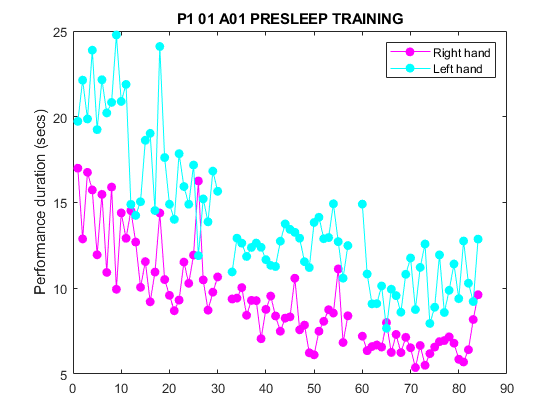

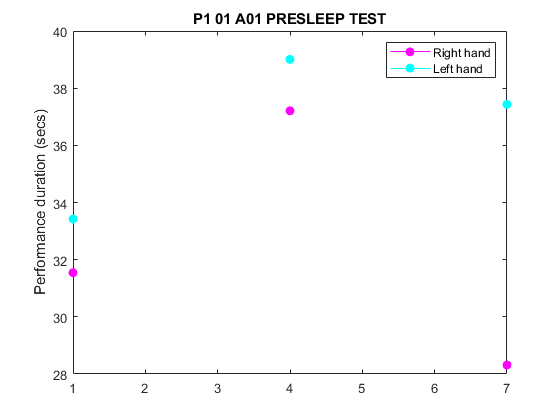

sessions = {'PreSleep_training', 'PreSleep_test', 'PostSleep_test'};

for i_subj = 1 : length(subjects)
    subj = subjects{i_subj};
    data_subj_dpath = fullfile(data_dpath, subj);

    for i_sess = 1 : length(sessions)
        sess = sessions{i_sess};
        list_dir = dir(fullfile(data_subj_dpath, [subj, '_', sess, '*.mat']));
        fnames = {list_dir.name};

        if isempty(fnames)
            continue;
        end

        figure();
        x_end = 0;

        for i_fname = 1 : length(fnames)
            src_fpath = fullfile(data_subj_dpath, fnames{i_fname});
            
            % Load the data
            data_loaded = load(src_fpath);
            blocks_info = data_loaded.blocks.info;
            input_onsets = data_loaded.blocks.input_onsets;

            durations = input_onsets(:, end) - input_onsets(:, 1);

            is_right = strcmp(blocks_info.hand, 'right');
            is_left = strcmp(blocks_info.hand, 'left');

            x = x_end+1 : x_end+length(durations)/2;

            % --- RIGHT HAND

            % Magenta color - circle markers - dashed line
            plot_str = 'm o -';
            marker_face_color = 'm';
            
            % Add legend only for the first loop interation
            if i_fname == 1
                p = plot(x, durations(is_right), plot_str, 'DisplayName', 'Right hand');
            else
                p = plot(x, durations(is_right), plot_str, 'HandleVisibility', 'off');
            end
            p.MarkerFaceColor = marker_face_color;
            hold on;

            % --- LEFT HAND

            % Cyan color - circle markers - dashed line
            plot_str = 'c o -'; 
            marker_face_color = 'c';
            
            % Add legend only for the first loop interation
            if i_fname == 1
                p = plot(x, durations(is_left), plot_str, 'DisplayName', 'Left hand');
            else
                p = plot(x, durations(is_left), plot_str, 'HandleVisibility', 'off');
            end
            p.MarkerFaceColor = marker_face_color;
            hold on;

            x_end = x_end + length(x) + 2;

        end

        legend('-DynamicLegend');
        legend('show');
        drawnow;
        hold off;

        title(upper(strrep([subj, ' ', sess], '_', ' ')));
        ylabel('Performance duration (secs)');
        
    end

end

## Clear & Close

for i = 1 : length(add2path)
    rmpath(add2path{i});
end

clearvars;
